J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2)

P_motor =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.




A = [-b/J   K/J
    -K/L   -R/L];
B = [0
    1/L];
C = [1   0];
D = 0;
motor_ss = ss(A,B,C,D)

motor_ss =
 
  A = 
          x1     x2
   x1    -10      1
   x2  -0.02     -2
 
  B = 
       u1
   x1   0
   x2   2
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



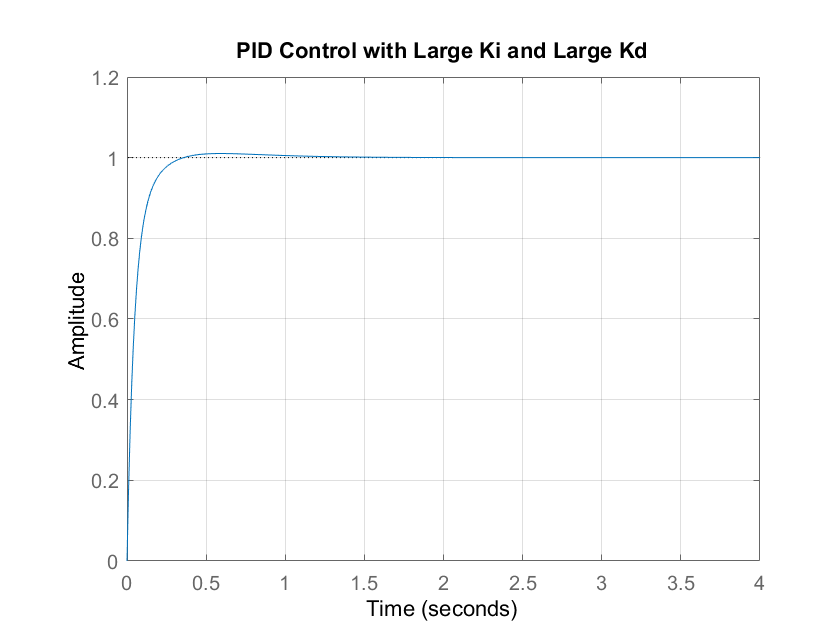


  linearSystemAnalyzer('step', P_motor, 0:0.1:5);
  
  
  % Adding PID Controller%
Kp = 100;
Ki = 200;
Kd = 10;
C = pid(Kp,Ki,Kd);
sys_cl = feedback(C*P_motor,1);
step(sys_cl, 0:0.01:4)
grid
title('PID Control')

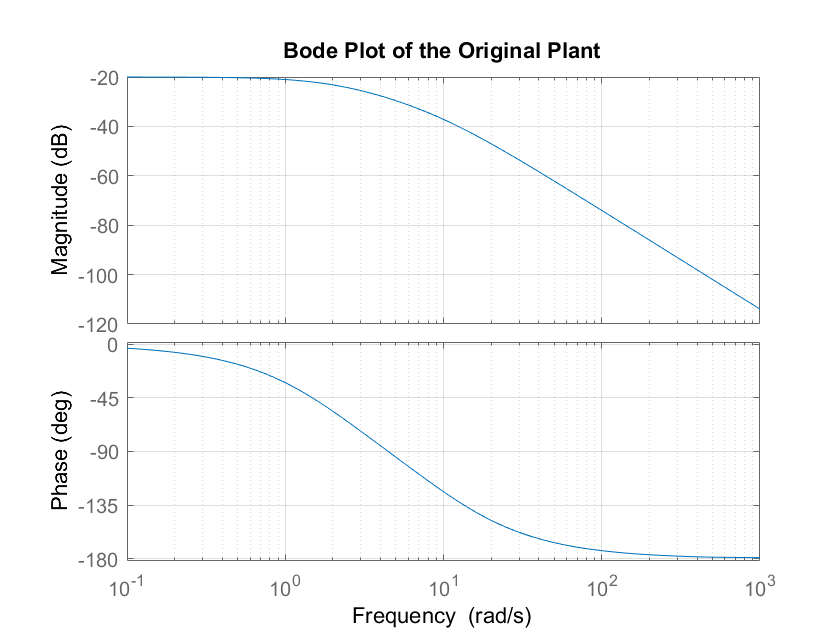


%Root Locus%

controlSystemDesigner('rlocus', P_motor) 
bode(P_motor)
grid
title('Bode Plot of the Original Plant')

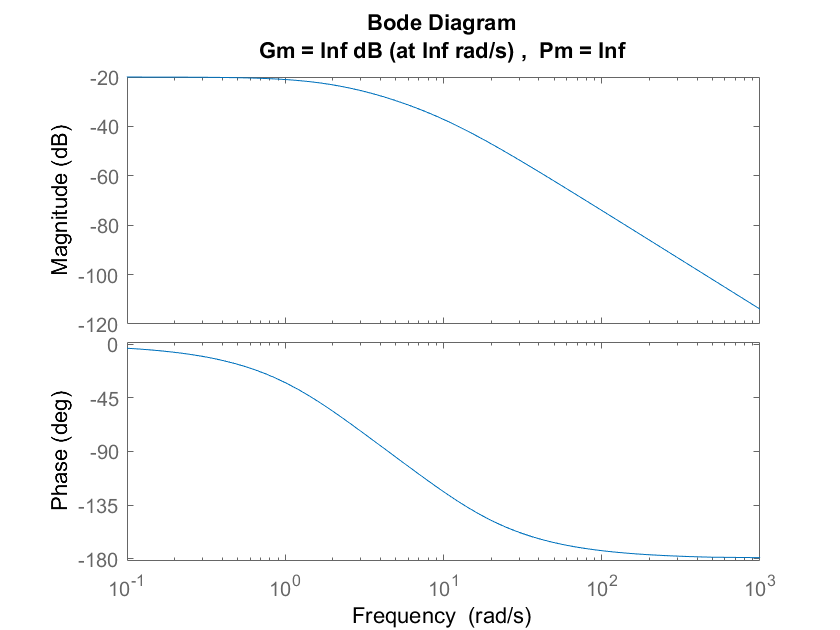


margin(P_motor)

[Gm,Pm,Wcg,Wcp] = margin(P_motor)

Gm = Inf

Pm = Inf

Wcg = Inf

Wcp = NaN